# TRANSMITTER

Different modulation schemes will all have the same average energy per bit

For the fare comparison between their BER later

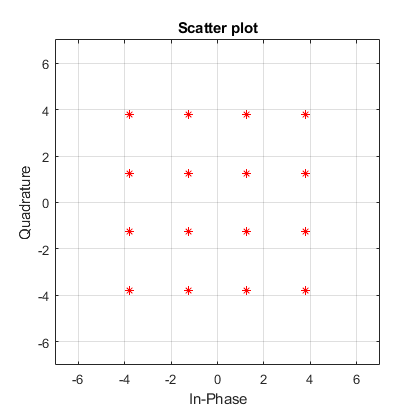

N_Bits = 4e5;
BitStream = randi([0 1],[1, N_Bits]);

Eb = 4;
Modulation_Order = 16;

[SymbolStream, Constellation] = Modulate(BitStream,Eb,Modulation_Order);

scatterplot(SymbolStream,1,0,'r*')
grid on
axis([-7 7 -7 7])

# CHANNEL

We will define the channel where it has the following proberties

The Real Component of the resultant vector has a gaussian ditribution:


$$h_R ~\aleph \left(\mu_R ,\sigma_R \right)$$


The Imaginary Component of the resultant vector has a gaussian ditribution:


$$h_I ~\aleph \left(\mu_I ,\sigma_I \right)$$


Notes:

1- Zero mean, Equal Variance channel is a Rayleigh channel where no LoS exists.

2-If any mean has a Non-Zero value, but still equal variances are used Ricean channel will be created.

3- The equal variances and zero mean proberty is what gives the phase of the channel the uniform distribution.

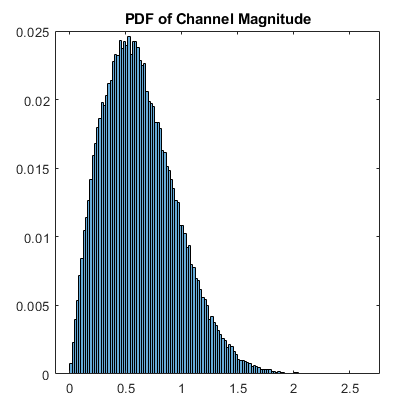

SNR_dB =0:20';
SNR = 10.^(SNR_dB/10);
SNR = diag(SNR);
N_Symbols = length(SymbolStream);


U_R = 0;       Sigma_R = 0.5;
U_I = 0;       Sigma_I = 0.5;
h_R = randn([1 N_Symbols])*Sigma_R + U_R;
h_I = randn([1 N_Symbols])*Sigma_I + U_I;

h = h_R + h_I*1j;

H_mag = histogram(abs(h),'Normalization','probability');
title('PDF of Channel Magnitude')

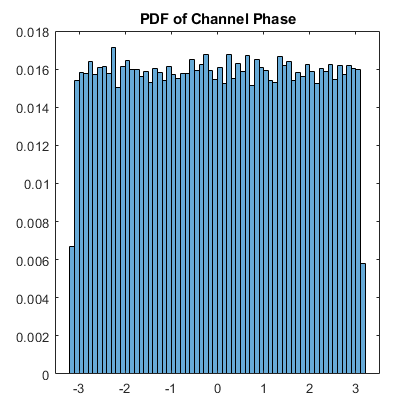

H_arg = histogram(angle(h),'Normalization','probability');
title('PDF of Channel Phase')


%Noise power will be determined by the SNR value
%SNR = Eb/No
No = Eb*SNR^-1;

N_c = randn([1 N_Symbols]);
N_s = randn([1 N_Symbols]);
N = N_c + N_s*1j;
N = (No/2)*repmat(N,length(SNR_dB),1);


## Sending the signal through the channel

Since the channel is represented by delta (One Resorvable Path)

Then the channel output will be simple multiplication and the channel value, where each symbol will only be scaled by a gain and added phase.

Then the White Gaussian Noise is added. 

Channel_OUT = SymbolStream.*h;
Channel_OUT = Channel_OUT + N;

# RECEIVER

#### 1) Equalizing the Channel 

**Since the channel gain is less than one it's expected that the noise is going to be amplfied during equalization increasing symbol errors.**

BER = zeros(length(SNR_dB),N_Bits);
for i = 1:length(SNR_dB)
ReceivedSymbolStream = Channel_OUT(i,:)./h;

#### 2) Applying Maximum Apsteriori decoding Plus Hard Decision Decoding

ReceivedBitStream = Decode(ReceivedSymbolStream, Constellation);

## Evaluating Bit Errors

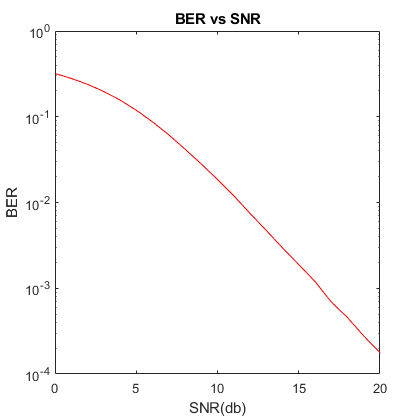

BER(i,:) = xor(ReceivedBitStream,BitStream);
end

BER = sum(BER,2)/N_Bits;

semilogy(SNR_dB, BER, 'r')
title('BER vs SNR')
xlabel('SNR(db)')
ylabel('BER')

function [SymbolStream, S] = Modulate(BitStream, Eb, Order)
%This function takes the bit stream and modulate it according
%to modulation order
%Modulation order varies from 2:BPSK 4:QPSK 16:16-QAM
%Eb: Energy per Bit

N_Bits = length(BitStream);

switch (Order)
    case 2
        A = sqrt(Eb);
        SymbolStream = (2*BitStream-1)*A;
        S = 2;
    
    case 4
        A = sqrt(Eb);
        %Creating the constellation:
        %Index represents the mapped bits - 1
        %ex: 00-> index:1 -> (-1-j)*A
        S(1) = - 1 - 1j;
        S(2) = - 1 + 1j;
        S(3) =   1 - 1j;
        S(4) =   1 + 1j;
        S = S*A;
        
        SymbolStream = reshape(BitStream,[2, N_Bits/2])';
        SymbolStream = num2str(SymbolStream);
        SymbolStream = bin2dec(SymbolStream)';
        SymbolStream = S(SymbolStream+1);
        
    case 16
        % Eb = 2.5E -> A = sqrt(E)
        A = sqrt(0.4*Eb);
        %Creating the constellation:
        %Index represents the mapped bits - 1
        %ex: 0000-> index:1 -> (-3-3j)*A
        S(1) = - 3 - 3j;
        S(2) = - 3 - 1j;
        S(3) = - 3 + 3j;
        S(4) = - 3 + 1j;
        S(5) = - 1 - 3j;
        S(6) = - 1 - 1j;
        S(7) = - 1 + 3j;
        S(8) = - 1 + 1j;
        S(9) =   3 - 3j;
       S(10) =   3 - 1j;
       S(11) =   3 + 3j;
       S(12) =   3 + 1j;
       S(13) =   1 - 3j;
       S(14) =   1 - 1j;
       S(15) =   1 + 3j;
       S(16) =   1 + 1j;
        S = S*A;
        
        SymbolStream = reshape(BitStream,[4, N_Bits/4])';
        SymbolStream = num2str(SymbolStream);
        SymbolStream = bin2dec(SymbolStream)';
        SymbolStream = S(SymbolStream+1);
        
        
        
    
end

end

function [Out_BitStream] = Decode(SymbolStream, S)
%This function takes the Symbol Stream after channel inversion
%And Decodes it according maximum Liklihood decoding
%aka: minimum distance to contellation point,
%since we are using eqiprobable signals
%Decoded symbols are directly converted to bits
%S is an array that carries the constellation points
%The Function then applies  Hard Decision Decoding
%Where its index is the equivalent binary value + 1

N_Symbols = length(SymbolStream);
Order = length(S);

if(S == 2)
    %BPSK case
    SymbolStream = real(SymbolStream);
    Out_BitStream(SymbolStream>0) = 1;
    Out_BitStream(SymbolStream<0) = 0;
    return 
end

SS_mod = repmat(SymbolStream,Order,1);
Rep_con = transpose(repmat(S,N_Symbols,1));
Distance = SS_mod - Rep_con;
Distance = abs(Distance);

[~, Index] = min(Distance);
%Output Bit stream in decimal
Out_BitStream = Index-1;
Out_BitStream = decimalToBinaryVector(Out_BitStream,log2(Order),'MSBFirst')';
Out_BitStream = reshape(Out_BitStream,1,N_Symbols*log2(Order));
end